%% Simulations and Data Storage
run("assignment_3.m");

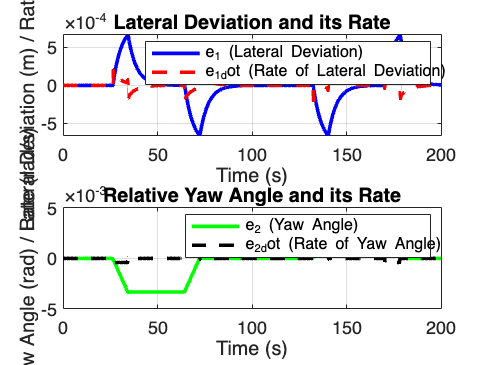

Unrecognized function or variable 'tight_layout'.

SIM     = sim('assignment_3_simulink');
t       = SIM.LKC_SIM.Time(:,1);
e_1     = SIM.LKC_SIM.Data(:,1);
e_1_dot = SIM.LKC_SIM.Data(:,2);
e_2     = SIM.LKC_SIM.Data(:,3);
e_2_dot = SIM.LKC_SIM.Data(:,4);

figure;

% Plot Lateral Deviation and its rate
subplot(2,1,1); % Create a subplot in the upper half of the figure
plot(t, e_1, 'b', 'LineWidth', 2); % Plot lateral deviation in blue
hold on;
plot(t, e_1_dot, 'r--', 'LineWidth', 2); % Plot rate of lateral deviation in red dashed line
title('Lateral Deviation and its Rate');
xlabel('Time (s)');
ylabel('Lateral Deviation (m) / Rate (m/s)');
legend('e_1 (Lateral Deviation)', 'e_1_dot (Rate of Lateral Deviation)');
grid on;

% Plot Relative Yaw Angle and its rate
subplot(2,1,2); % Create a subplot in the lower half of the figure
plot(t, e_2, 'g', 'LineWidth', 2); % Plot yaw angle in green
hold on;
plot(t, e_2_dot, 'k--', 'LineWidth', 2); % Plot rate of yaw angle in black dashed line
title('Relative Yaw Angle and its Rate');
xlabel('Time (s)');
ylabel('Yaw Angle (rad) / Rate (rad/s)');
legend('e_2 (Yaw Angle)', 'e_2_dot (Rate of Yaw Angle)');
grid on;

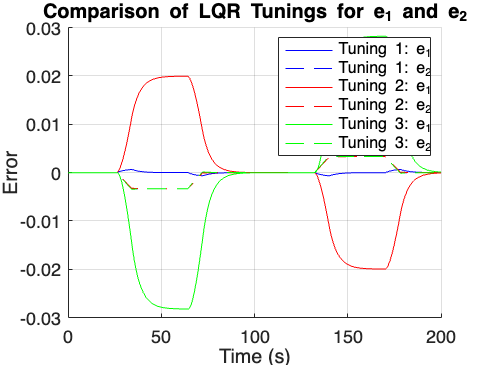

% Define the constant R matrix
R = 1;

% Different Q matrices for LQR tuning
Q1 = diag([10, 200, 10, 300]);   % Original tuning
Q2 = diag([20, 400, 20, 600]);   % More aggressive control on all states
Q3 = diag([5, 100, 5, 150]);     % Less aggressive control on all states

% Array of Q matrices for looping
Q_matrices = {Q1, Q2, Q3};

% Store simulation results
simResults = struct();

% Loop through each Q matrix, apply LQR, simulate in Simulink, and store results
for i = 1:length(Q_matrices)
    % Compute the LQR controller gain
    [K, ~, ~] = lqr(A, B_1, Q_matrices{i}, R);

    % Run the Simulink model
    SIM = sim('assignment_3_simulink');
    
    % Extract data from SIM structure
    t       = SIM.LKC_SIM.Time(:,1);
    e_1     = SIM.LKC_SIM.Data(:,1);
    e_1_dot = SIM.LKC_SIM.Data(:,2);
    e_2     = SIM.LKC_SIM.Data(:,3);
    e_2_dot = SIM.LKC_SIM.Data(:,4);
    
    % Save results in a structure for plotting later
    simResults(i).time      = t;
    simResults(i).e_1       = e_1;
    simResults(i).e_1_dot   = e_1_dot;
    simResults(i).e_2       = e_2;
    simResults(i).e_2_dot   = e_2_dot;
end

% Plot the results
figure;
hold on;
colors = {'b', 'r', 'g'}; % Colors for each simulation plot
for i = 1:length(simResults)
    plot(simResults(i).time, simResults(i).e_1, colors{i}, 'DisplayName', sprintf('Tuning %d: e_1', i));
    plot(simResults(i).time, simResults(i).e_2, colors{i} + "--", 'DisplayName', sprintf('Tuning %d: e_2', i));
end
title('Comparison of LQR Tunings for e_1 and e_2');
xlabel('Time (s)');
ylabel('Error');
legend show;
grid on;

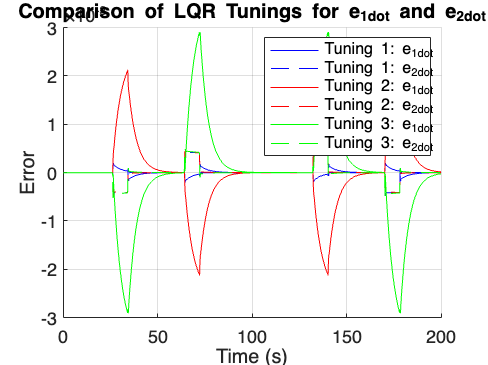


figure;
hold on;
colors = {'b', 'r', 'g'}; % Colors for each simulation plot
for i = 1:length(simResults)
    plot(simResults(i).time, simResults(i).e_1_dot, colors{i}, 'DisplayName', sprintf('Tuning %d: e_1_{dot}', i));
    plot(simResults(i).time, simResults(i).e_2_dot, colors{i} + "--", 'DisplayName', sprintf('Tuning %d: e_2_{dot}', i));
end
title('Comparison of LQR Tunings for e_1_{dot} and e_2_{dot}');
xlabel('Time (s)');
ylabel('Error');
legend show;
grid on;

% Define different rear axle cornering stiffness values and other parameters
C_r_values = [2*57000, 2*47000, 2*67000]; % Different stiffness values
Q = diag([10, 200, 10, 300]); % LQR weighting matrix
R = 1; % Control weighting factor
simTime = '10'; % Total simulation time as string

% Enable Fast Restart for the simulation
set_param('assignment_3_simulink', 'FastRestart', 'on');

% Loop through each C_r value
for i = 1:length(C_r_values)
    C_r = C_r_values(i);
    
    % Update the C_r in Simulink
    set_param('assignment_3_simulink', 'C_r', num2str(C_r));
    
    % Recalculate LQR controller gain K
    [K, ~, ~] = lqr(A, B_1, Q, R);
    set_param('assignment_3_simulink', 'Gain', mat2str(K));
    
    % Run the Simulink model with updated parameters
    simOut = sim('assignment_3_simulink', 'StopTime', simTime);
    
    % Extract and store results
    t_all{i} = simOut.tout;
    control_input_all{i} = simOut.yout{1}.Values.Data; % Modify according to how data is structured in your Simulink outputs
end

block_diagram does not have a parameter named 'C_r'


% Disable Fast Restart after simulations
set_param('assignment_3_simulink', 'FastRestart', 'off');

% Plot results
figure;
hold on;
colors = ['b', 'r', 'g'];
legends = {'Original C_r', 'Decreased C_r', 'Increased C_r'};
for i = 1:length(t_all)
    plot(t_all{i}, control_input_all{i}, colors(i));
end
title('Control Input Profiles for Varying Rear Axle Stiffness');
xlabel('Time (s)');
ylabel('Control Input');
legend(legends);
grid on;
